
%%
clear, clc;
K = 6;
%W = 2000*rand(K,2);
W = PointGenerator(1000,K);

deltaR =   309.0076
 -162.2687
  171.7769
  286.3513
   59.1868
  284.5523


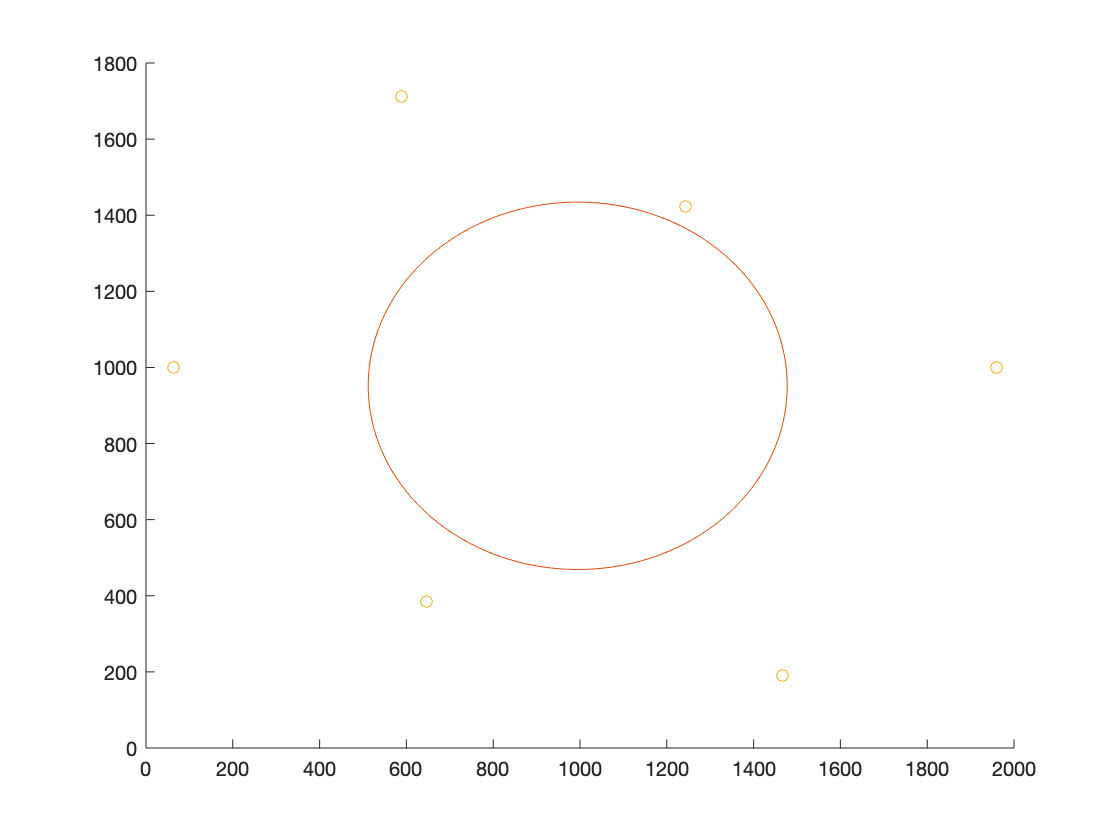


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     902   -8.007982e-03    0.000e+00    1.459e-01


    1    1804   -1.749398e-02    0.000e+00    2.282e-02    4.114e-01
    2    2706   -1.171701e-01    0.000e+00    2.282e-02    4.429e-01
    3    3614   -2.506334e-01    1.648e-03    3.413e-02    2.082e+00
    4    4519   -2.863427e-01    9.712e-04    3.413e-02    2.816e-01
    5    5427   -3.157277e-01    0.000e+00    3.445e-02    4.842e-01
    6    6330   -4.425535e-01    0.000e+00    3.845e-02    8.933e-01
    7    7235   -4.818085e-01    0.000e+00    3.845e-02    3.116e-01
    8    8155   -4.820491e-01    0.000e+00    2.891e-02    9.894e-03
    9    9059   -4.837977e-01    0.000e+00    2.889e-02    9.994e-03
   10    9967   -4.884079e-01    0.000e+00    3.219e-02    2.105e-02
   11   10879   -4.918248e-01    0.000e+00    2.913e-02    3.612e-02
   12   11785   -4.930247e-01    0.000e+00    2.913e-02    9.288e-03
   13   12695   -4.933840e-01    0.000e+00    2.818e-02    9.071e-03
   14   13599   -4.957654e-01    0.000e+00    2.818e-02    1.653e-02
   15   14513   -4.960906e-01    0

d_min = 100;
T = 210;
H = 100;
NoisePower = 10^(-14);
d0 = 1;
Rho0 = 10^(-6);
Pmax = 0.1;
Vmax = 50;
epsilon = 10^-2;
M = 1;
%N = Vmax*T/(H*epsilon);
N = 150;
Tau = 100;
N2 = N*Tau;
%Slot_assignment = Tau * A
deltaT = T/N;
Max_Dist = deltaT * Vmax;
history.x = [];
history.fval = [];
%%

%%
GeometricCenter = sum(W)/K;
Radius = max(vecnorm(W - GeometricCenter,2,2));
RadiusMax = Vmax * T / (2*pi);

filepath = 'packings/cci' + string(M) + '.txt';
Radii = load('radius.txt');
Radius_cp = Radii(M,2)*Radius/2;
cp_coords = load(filepath);
cp_coords = cp_coords(:, 2:3)*Radius;
R_traj = min(RadiusMax, Radius_cp);

Theta = linspace(0, 2*pi, N);
Small_Trajectory_Coords = GeometricCenter + cp_coords;
Xs = Small_Trajectory_Coords(:,1) + R_traj*cos(Theta);
Xs = reshape(Xs, [M, 1, N]);
Ys = Small_Trajectory_Coords(:,2) + R_traj*sin(Theta);
Ys = reshape(Ys, [M, 1, N]);
Trajectory_guess = [Xs, Ys];
%Q_guess = 
%plot(Xs(1,:), Ys(1,:), Xs(2,:), Ys(2,:));

for i = 1:M
    hold on
    plot(Xs(i,:), Ys(i,:));
end
scatter(W(:,1), W(:,2))
%%
P_init = ones(M, N)*Pmax;
%A_init = repmat([0.99*ones(K,1) zeros(K,M-1)], [1,1,N]);
A_init = rand(K,M);
A_init = .99 * A_init / sum(A_init, 'all');
A_init = repmat(A_init, [1,1,N]);
Q_init = Trajectory_guess;
%%
[obj, ~, ~] = UserScheduling(A_init, P_init, Trajectory_guess, K, M, N, Rho0, H, W, NoisePower);
%% Defining Optimization Setup
%A = zeros(K, M, N);
A = optimvar('A', K,M,N, 'Type', 'continuous', 'LowerBound', 0, "UpperBound", 1);
%Q = zeros(M, 2, N);
Q = optimvar('Q', M,2,N, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', 2000);
%P = zeros(M,N);
P = optimvar('P', M,N, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', Pmax);
nu = optimvar('nu', 1, 'Type', 'continuous', 'LowerBound',0, "UpperBound", inf);


[f, nu_found, A_sum_k, A_sum_m] = fcn2optimexpr(@UserSchedulingConvex, nu, A, P_init, Q_init, K, M, N, Rho0, H, W, NoisePower);
problem = optimproblem('ObjectiveSense', 'max');
problem.Objective = f;

problem.Constraints.cons1 = A_sum_k <= 1;
problem.Constraints.cons2 = A_sum_m <= 1;
problem.Constraints.nu_found = nu_found >= nu;
%show(problem);

x0.A = A_init;
x0.nu = obj;
options = optimoptions('fmincon','OutputFcn',@outfun, 'Display', 'iter', 'MaxFunctionEvaluations', 100000, 'OptimalityTolerance', 1.0000e-04);
[sol, fval, exitflag, output] = solve(problem, x0, 'Options', options);

%obj = fcn2optimexpr
%problem.Objective = SINR
%%


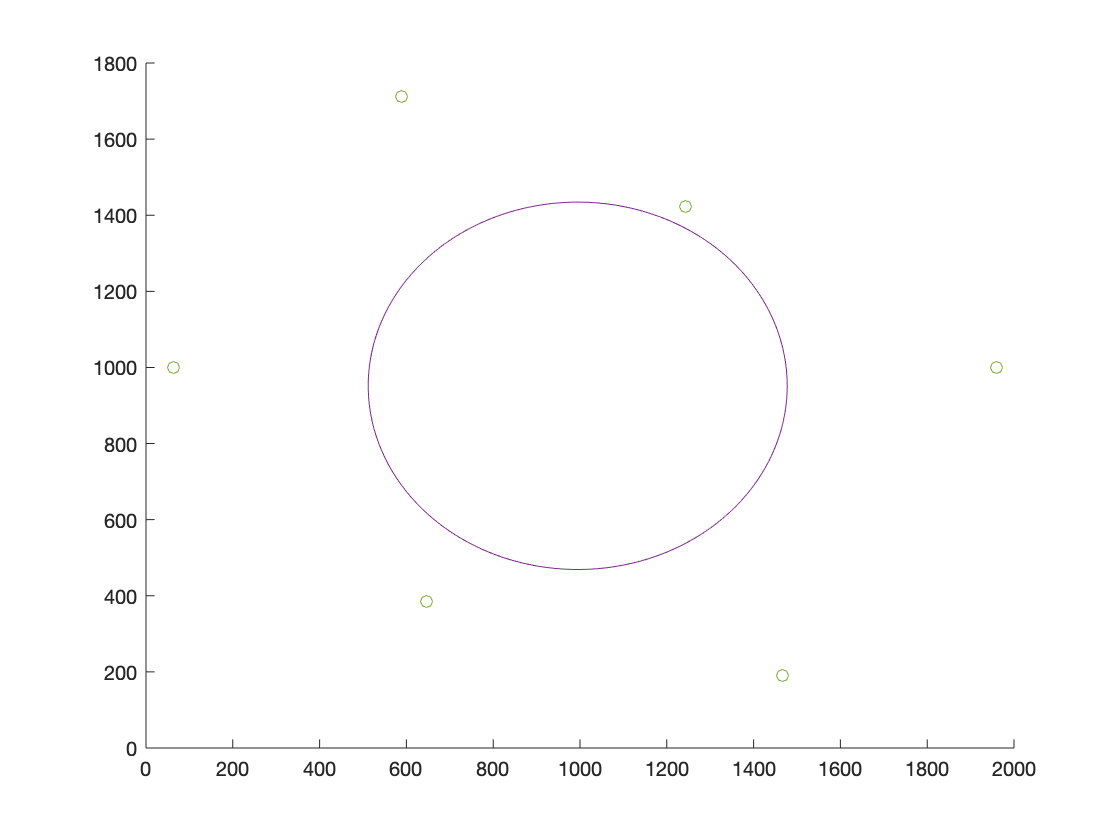

Q2 = Q_init;
Xs = Q2(:, 1, :);
Ys = Q2(:, 2, :);
Xs = reshape(Xs,[M,N]);
Ys = reshape(Ys, [M,N]);
for i = 1:M
    hold on
    plot(Xs(i,:), Ys(i,:));
end
scatter(W(:,1), W(:,2));
hold off;